# Spiking Neural Network that Maps from Generalized to Cartesian Coordinates

# Overview

- Program for calculating forward kinematics.

- Incorporate sigmoid sensory encoding. - ixnay

- Compare with original and show more resilient.

- Incorporate accuracy and lag calculations into design program, i.e. give joint twists and number of sensory neurons for each one, calculate everything else for me. 

- Make design process as automatic as possible. 

- Try out on different legs. 

# Methods

# Introduction

The kinematics of the bug include the lengths of the tibia, femur, and thorax.

- *R* is the maximum expected membrance voltage above rest, 20 mV. 

- *E* is the reversal potential above the resting membrane potential, 70 mV.

- $l_{\textrm{ti}\;}$ is the tibia length, 10 cm.

- $l_{\textrm{fe}}$ is the femur length, 10 cm.

- $l_{\textrm{th}}$ is the thorax, positioned at 0. 

## 3.1 Initial Variables

clear
for i

    
    R = 20; % [mV]
    Ein = -10;
    Eex = 70; % [mV]
    
    
    l_ti = 0.10; % tibia length = 10 cm
    l_fe = 0.10; % femur length = 10 cm
    l_th = 0; % thorax at 0

Table 2 Cruse, H. et al. - angle value describing position of rotational axis of th-coxa: middle leg 

- $\alpha \;$ is the protraction/retraction angle around the thorax - coxa

- $\beta \;$ is the levation/depression angle around the coxa-trochanter

- $\gamma \;$ is the flexion/extension angle around the femur - tibia

    theta1 = linspace(deg2rad(-45),deg2rad(45),5); % alpha in paper above --> can change 5 to 1
    theta2 = linspace(deg2rad(-45),deg2rad(45),5); % beta in paper above
    theta3 = linspace(deg2rad(-150),0,5); % gamma in paper above

## 3.2 Transformation from the Thorax frame to the End Effector

Describes the transformation from the thorax frame to the end effector.

### Step 1. Define the Zero Configuration. 

Frame in the zero configuration. 

    % global frame = thorax frame
    g_th = [0 0 0];
    
    % identity matrix
    I = [1 0 0;...
        0 1 0;...
        0 0 1]

I =      1     0     0
     0     1     0
     0     0     1


    % zero configuration 3x1 translatio vector
    g_T_l2 = [0 (l_fe+l_ti) l_th]' % where the foot is when all angles are 0.

g_T_l2 =          0
    0.2000
         0


    % Transformation from the thorax frame to the end effector in the zero
    % config. 
    g_foot_thorax_zero = [I g_T_l2;...
                     0 0 0 1]

g_foot_thorax_zero =     1.0000         0         0         0
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


### Step 2. Find the joint twists - zeta

- 
$$v=\textrm{cross}\left(\omega_{i\;} ,q_i \right)$$


- angle value describing position of rotational axis of thorax - coxa of the middle leg: psi = 37 degrees ---> Table 2 of Cruse, H. et al. 

    omega1 = [0 sind(37) cosd(37)]'; % omega 1 = omega for thorax/coxa
    q1 = [0 0 l_th]';
    v1 = cross(-omega1,q1);
    zeta1 = [v1;...
            omega1]

zeta1 =          0
         0
         0
         0
    0.6018
    0.7986


    
    omega2 = [-1 0 0]'; % omega 2 = omega for the coxa-trochanter
    v2 = cross(-omega2,q1);
    zeta2 = [v2;...
            omega2]

zeta2 =      0
     0
     0
    -1
     0
     0


    
    omega3 = [-1 0 0]'; % omega 3 = omega for the femur-tibia
    q2 = [0 l_fe l_th]';
    v3 = cross(-omega3,q2);
    zeta3 = [v3;...
            omega3]

zeta3 =          0
         0
    0.1000
   -1.0000
         0
         0


### Step 3. Calculate the rotation matrix omegas in cross product matrix notation:

    omega_skew1 = [0 -omega1(3) omega1(2);...
                  omega1(3) 0 -omega1(1);...
                  -omega1(2) omega1(1) 0]

omega_skew1 =          0   -0.7986    0.6018
    0.7986         0         0
   -0.6018         0         0


    omega_skew2 = [0 -omega2(3) omega2(2);...
                  omega2(3) 0 -omega2(1);...
                  -omega2(2) omega2(1) 0]

omega_skew2 =      0     0     0
     0     0     1
     0    -1     0


    omega_skew3 = [0 -omega3(3) omega3(2);...
                  omega3(3) 0 -omega3(1);...
                  -omega3(2) omega3(1) 0]

omega_skew3 =      0     0     0
     0     0     1
     0    -1     0


    output = NaN(5,5,5,6) % for tuning

output = output(:,:,1,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,2,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,3,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,4,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,5,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,1,2) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN

### Rodriques' Rotation Formula:

    n = 5;
    m = 1;
    for i = 1:n
        for j = 1:n
            for k = 1:n
                exp_omega_skew1 = I + (omega_skew1).*sin(theta1(i)) + (omega_skew1)^2.*(1-cos(theta1(i)));
                exp_omega_skew2 = I + (omega_skew2).*sin(theta2(j)) + (omega_skew2)^2.*(1-cos(theta2(j)));
                exp_omega_skew3 = I + (omega_skew3).*sin(theta3(k)) + (omega_skew3)^2.*(1-cos(theta3(k)));
                

8.000000e-01
1.600000e+00
2.400000e+00
3.200000e+00
4
4.800000e+00
5.600000e+00
6.400000e+00
7.200000e+00
8
8.800000e+00
9.600000e+00
1.040000e+01
1.120000e+01
12
1.280000e+01
1.360000e+01
1.440000e+01
1.520000e+01
16
1.680000e+01
1.760000e+01
1.840000e+01
1.920000e+01
20
2.080000e+01
2.160000e+01
2.240000e+01
2.320000e+01
24
2.480000e+01
2.560000e+01
2.640000e+01
2.720000e+01
28
2.880000e+01
2.960000e+01
3.040000e+01
3.120000e+01
32
3.280000e+01
3.360000e+01
3.440000e+01
3.520000e+01
36
3.680000e+01
3.760000e+01
3.840000e+01
3.920000e+01
40
4.080000e+01
4.160000e+01
4.240000e+01
4.320000e+01
44
4.480000e+01
4.560000e+01
4.640000e+01
4.720000e+01
48
4.880000e+01
4.960000e+01
5.040000e+01
5.120000e+01
52
5.280000e+01
5.360000e+01
5.440000e+01
5.520000e+01
56
5.680000e+01
5.760000e+01
5.840000e+01
5.920000e+01
60
6.080000e+01
6.160000e+01
6.240000e+01
6.320000e+01
64
6.480000e+01
6.560000e+01
6.640000e+01
6.720000e+01
68
6.880000e+01
6.960000e+01
7.040000e+01
7.120000e+01
72
7.280000e+01

### Step 4. Calculate the translation.

                % calculate translation
                t1 = (I-exp_omega_skew1)*(cross(omega1,v1)) + omega1*(omega1)'*(v1)*(theta1(i));
                t2 = (I-exp_omega_skew2)*(cross(omega2,v2)) + omega2*(omega2)'*(v2)*(theta2(j));
                t3 = (I-exp_omega_skew3)*(cross(omega3,v3)) + omega3*(omega3)'*(v3)*(theta3(k));
                

### Step 5. Calculate the matrix exponential.

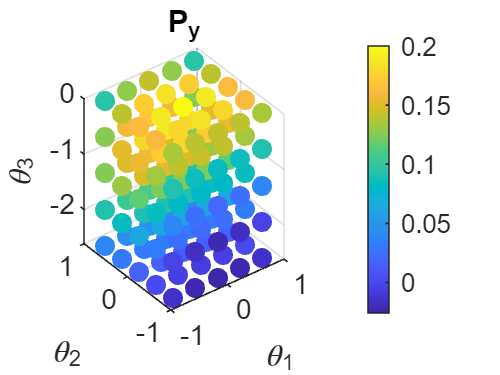

                % calculate the matrix exponential
                exp_Twist_skew1 = [exp_omega_skew1 t1;...
                                   0 0 0 1];

                exp_Twist_skew2 = [exp_omega_skew2 t2;...
                                   0 0 0 1];
                exp_Twist_skew3 = [exp_omega_skew3 t3;...
                                   0 0 0 1];
                

### Step 6. Compose the structure equation.

                % compose the structure equation
                g_foot_thorax = exp_Twist_skew1*exp_Twist_skew2*exp_Twist_skew3*g_foot_thorax_zero;
                output(i,j,k,1)=(theta1(i));
                output(i,j,k,2)=(theta2(j));
                output(i,j,k,3)=(theta3(k));
                output(i,j,k,4)=g_foot_thorax(1,4);
                output(i,j,k,5)=g_foot_thorax(2,4);
                output(i,j,k,6)=g_foot_thorax(3,4);
                fprintf('%i\n',100*m/n^3)
                m=m+1;
            end
        end 
    end 

## 3.3 Tuning Parameters within the Model

$P_x$ Output is the output(:,4)

$P_y$ Output is the output(:,5)

$P_z$ Output is the output(:,6)

### Figure: Scatterplot 

    % we want Py for now
    figure
    scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),[],reshape(output(:,:,:,5),[],1),'filled')
    title('P_y')
    xlabel('\theta_1')
    ylabel('\theta_2')
    zlabel('\theta_3')
    colorbar

Time vector:

    tmax = 5; % [s]
    dt = 0.01; % [s]
    t = 0:dt:tmax; % [s]
    numSteps = length(t);
    
    minPy = min(output(:,:,:,5),[],'all');
    maxPy = max(output(:,:,:,5),[],'all');
    kvar = (output(:,:,:,5) - minPy)/(maxPy - minPy);

### Sinusoids

Sinusoid Periods:

    T1 = 1;

bell_1 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

    T2 = 0.85;

bell1func = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


    T3 = 0.7;
    

bell_2 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

    % List of theta values as a function of time for each angle:

bell2func = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


    
    th1list = 1*(range(theta1)*sin(2*pi*t/T1)/2 + mean(theta1));

bell_3 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

    th2list = 1*(range(theta2)*sin(2*pi*t/T2)/2 + mean(theta2));

bell3func = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


    th3list = 1*(range(theta3)*sin(2*pi*t/T3)/2 + mean(theta3));
    
    numNeurons=n^3;
    
    Ui = NaN(numSteps,numNeurons);
    Usoma = NaN(n,n,n);
    Py = NaN(numSteps,1);

## Width

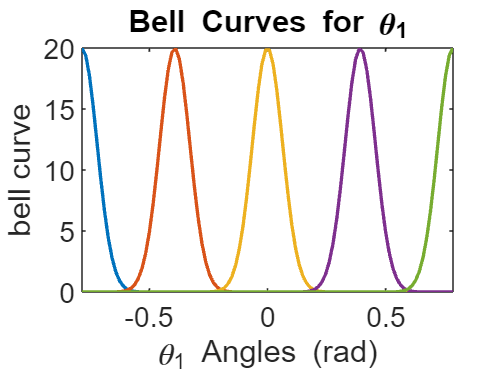

    c = 300; % width

Changing the width value, or c, will change the sigmoid function (erf) to be steeper or flatter, i.e.,

- To flatten the sigmoid, c = 1.

- To steepen the sigmoid, c = 15. 

    theta1test = linspace(min(theta1),max(theta1),100);
    theta2test = linspace(min(theta2),max(theta2),100);
    theta3test = linspace(min(theta3),max(theta3),100);

Create the bell functions:

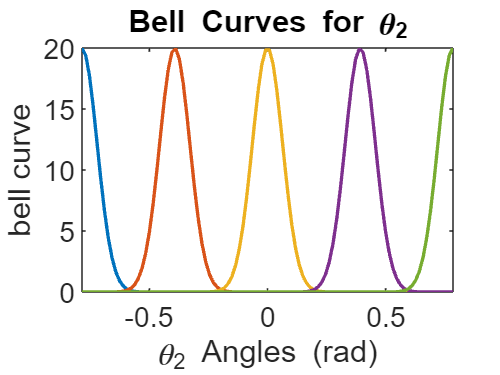

    %bell_1 = R*exp(-c*(theta1test-b).^2)
    bell_1 = R*exp(-c/range(theta1)^2*(theta1test-theta1').^2)
    bell1func = @(x) exp(-c/range(theta1)^2*(x-theta1').^2)
    

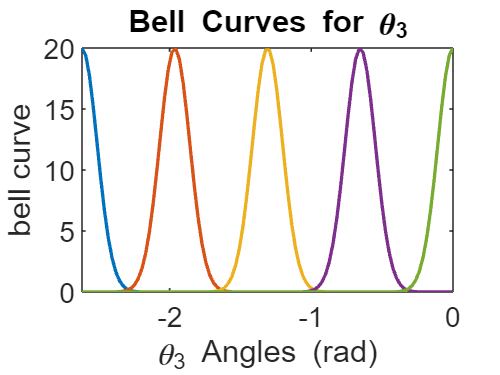

    bell_2 = R*exp(-c/range(theta2)^2*(theta2test-theta2').^2)
    bell2func = @(x) exp(-c/range(theta2)^2*(x-theta2').^2)
    
    bell_3 = R*exp(-c/range(theta3)^2*(theta3test-theta3').^2)
    bell3func = @(x) exp(-c/range(theta3)^2*(x-theta3').^2)

    figure 
    grid on

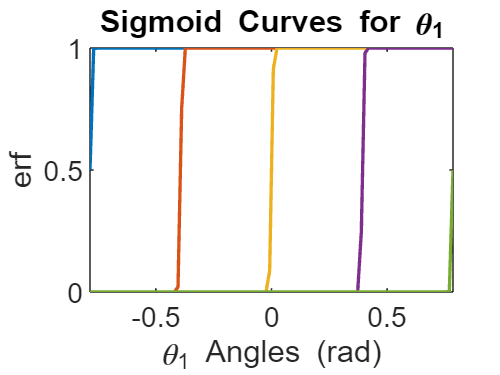

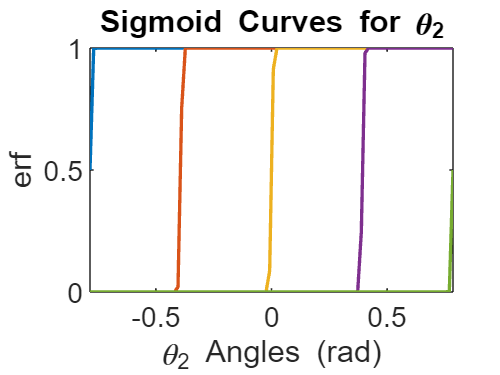

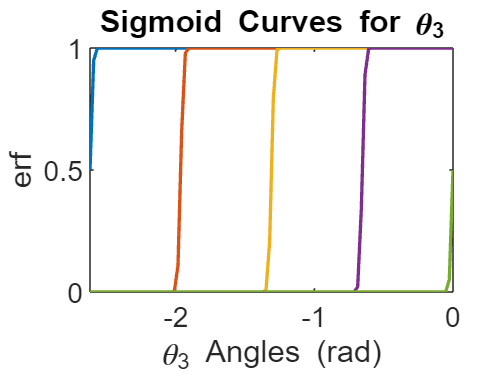

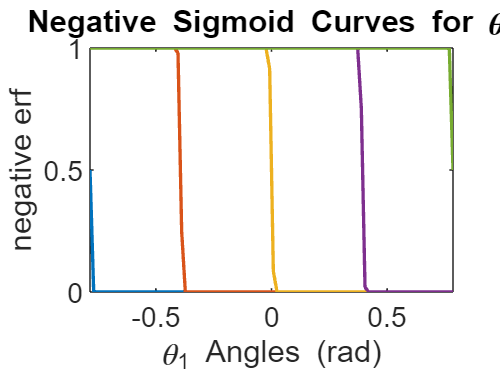

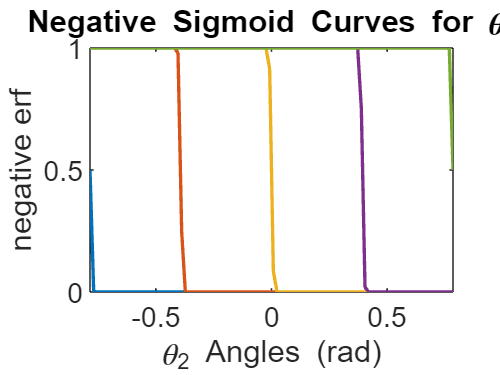

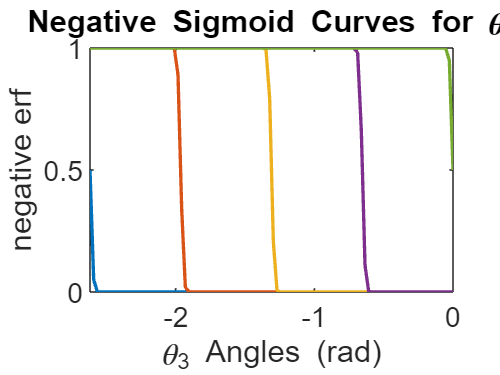

    plot(theta1test,bell_1,'linewidth',1)
    xlabel('\theta_1 Angles (rad)')

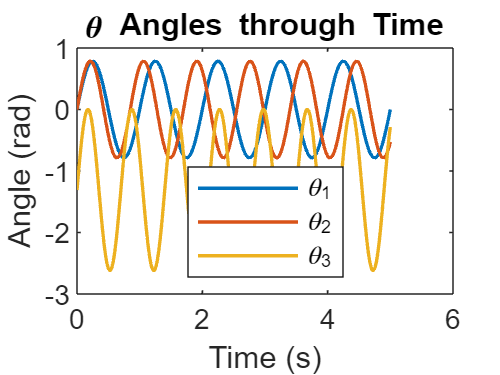

    ylabel('bell curve')
    title('Bell Curves for \theta_1')
    xlim([min(theta1),max(theta1)])
    
    figure 
    grid on
    plot(theta2test,bell_2,'linewidth',1)
    xlabel('\theta_2 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_2')

    xlim([min(theta2),max(theta2)])
    
    figure 
    grid on
    plot(theta3test,bell_3,'linewidth',1)
    xlabel('\theta_3 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_3')
    xlim([min(theta3),max(theta3)])
    
    Plot the theta lists, or the theta angles through time:
    figure
    grid on
    plot(t,th1list,'linewidth',1)
    hold on
    plot(t,th2list,'linewidth',1)
    plot(t,th3list,'linewidth',1)
    xlabel('Time (s)')
    ylabel('Angle (rad)')
    legend('\theta_1','\theta_2','\theta_3','location','south')
    title('\theta Angles through Time')


# Results

Scratch Work Code from 2-6-2023: 

What order to calculate l's?

- Lowest to highest total activity.

- Break symmetry in network.

- Theta_hip_max doesn't equal Theta_knee_ma x, etc.

Calculate all U's.

Formulate the function to change G's until Upy is correct.

Only want to calculate G's that are currently unknown.

Follow "elimination" process. 

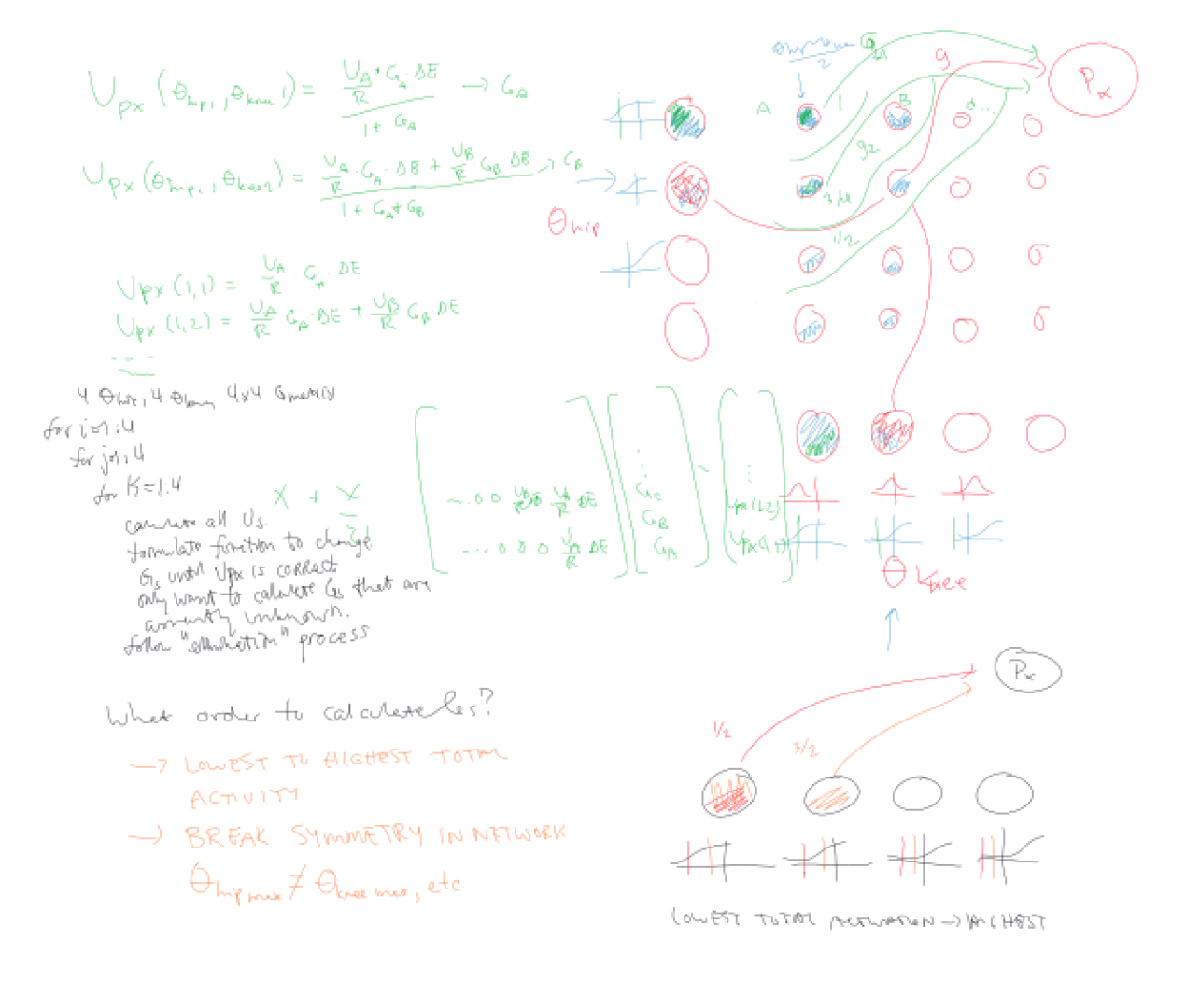


$$k=\frac{\left(P_y -\min \left(P_y \right)\right)}{\left(\max \left(P_y \right)-\min \left(P_y \right)\right)}$$



$$U_{P_y } \left(\theta_{x_1 } ,\theta_{y_1 } ,\theta_{z_1 } \right)=\frac{\left(\frac{U_A }{R}*G_A *\Delta E\;\right)}{\left(1+G_A \right)}$$


$\Delta E=60\;\textrm{mV}$ which is the reversal potential of the chemical synapse. 


$$G_{y_i } =G_A$$


Tuning:

- Make 5x5x5 grid of angles and calculate every Usoma value. Then use this to calculate all Gyi’s.

    Usomadesired = kvar*R;

Testing:

- When testing: use varying-angles-over-time data (the theta lists or thetatests?), by running those angles through the network and seeing what Usomas you get out.

## Binary Code - Least Squares Problem

    b = Usomadesired(:);
    Evec = Eex + zeros(size(kvar(:)));
    Evec(kvar<0) = Ein;
    Gmax = (kvar(:)*R)./(Evec - (kvar(:)*R));
    Gmax_bell_OG = Gmax;
    
    %To "blur" or "smooth out" the Gmax values, we will need to keep them in an
    %N-D grid (i.e., a cube when N=3). We will convolve this with a "kernel"
    %that represents how much our bellcurves overlap.
    GmaxCube = (kvar*R)./(Eex - kvar*R);
    if any(GmaxCube < 0)
        error('Synaptic conductance values must be greater than or equal to 0.')
    end


### Convolution:

    c = 15; % width that we actually want for our sensory system/decoder network.

bell_1new =    20.0000   19.9694   19.8779   19.7264   19.5162   19.2492   18.9279   18.5550   18.1339   17.6682   17.1618   16.6190   16.0442   15.4419   14.8168   14.1736   13.5168   12.8511   12.1808   11.5102   10.8433   10.1838    9.5352    8.9006    8.2829    7.6844    7.1075    6.5537    6.0246    5.5213    5.0446    4.5950    4.1726    3.7775    3.4094    3.0677    2.7518    2.4609    2.1941    1.9502    1.7281    1.5266    1.3445    1.1805    1.0333    0.9017    0.7845    0.6804    0.5883    0.5072
    7.8321    8.4356    9.0578    9.6962   10.3478   11.0095   11.6777   12.3486   13.0181   13.6820   14.3358   14.9750   15.5948   16.1906   16.7579   17.2920   17.7886   18.2435   18.6529   19.0132   19.3212   19.5742   19.7699   19.9065   19.9828   19.9981   19.9522   19.8456   19.6793   19.4547   19.1739   18.8394   18.4541   18.0215   17.5452   17.0294   16.4781   15.8960   15.2876   14.6575   14.0105   13.3511   12.6838   12.0131   11.3430   10.6776   10.0205    9.3751    8.7

bell1funcnew = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


    bell_1new = R*exp(-c/range(theta1)^2*(theta1test-theta1').^2)
    bell1funcnew = @(x) exp(-c/range(theta1)^2*(x-theta1').^2)

bell_2new =    20.0000   19.9694   19.8779   19.7264   19.5162   19.2492   18.9279   18.5550   18.1339   17.6682   17.1618   16.6190   16.0442   15.4419   14.8168   14.1736   13.5168   12.8511   12.1808   11.5102   10.8433   10.1838    9.5352    8.9006    8.2829    7.6844    7.1075    6.5537    6.0246    5.5213    5.0446    4.5950    4.1726    3.7775    3.4094    3.0677    2.7518    2.4609    2.1941    1.9502    1.7281    1.5266    1.3445    1.1805    1.0333    0.9017    0.7845    0.6804    0.5883    0.5072
    7.8321    8.4356    9.0578    9.6962   10.3478   11.0095   11.6777   12.3486   13.0181   13.6820   14.3358   14.9750   15.5948   16.1906   16.7579   17.2920   17.7886   18.2435   18.6529   19.0132   19.3212   19.5742   19.7699   19.9065   19.9828   19.9981   19.9522   19.8456   19.6793   19.4547   19.1739   18.8394   18.4541   18.0215   17.5452   17.0294   16.4781   15.8960   15.2876   14.6575   14.0105   13.3511   12.6838   12.0131   11.3430   10.6776   10.0205    9.3751    8.7

bell2funcnew = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


    bell_2new = R*exp(-c/range(theta2)^2*(theta2test-theta2').^2)
    bell2funcnew = @(x) exp(-c/range(theta2)^2*(x-theta2').^2)

bell_3new =    20.0000   19.9694   19.8779   19.7264   19.5162   19.2492   18.9279   18.5550   18.1339   17.6682   17.1618   16.6190   16.0442   15.4419   14.8168   14.1736   13.5168   12.8511   12.1808   11.5102   10.8433   10.1838    9.5352    8.9006    8.2829    7.6844    7.1075    6.5537    6.0246    5.5213    5.0446    4.5950    4.1726    3.7775    3.4094    3.0677    2.7518    2.4609    2.1941    1.9502    1.7281    1.5266    1.3445    1.1805    1.0333    0.9017    0.7845    0.6804    0.5883    0.5072
    7.8321    8.4356    9.0578    9.6962   10.3478   11.0095   11.6777   12.3486   13.0181   13.6820   14.3358   14.9750   15.5948   16.1906   16.7579   17.2920   17.7886   18.2435   18.6529   19.0132   19.3212   19.5742   19.7699   19.9065   19.9828   19.9981   19.9522   19.8456   19.6793   19.4547   19.1739   18.8394   18.4541   18.0215   17.5452   17.0294   16.4781   15.8960   15.2876   14.6575   14.0105   13.3511   12.6838   12.0131   11.3430   10.6776   10.0205    9.3751    8.7

bell3funcnew = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


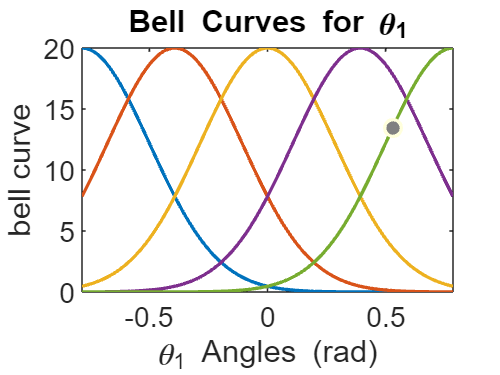

    bell_3new = R*exp(-c/range(theta3)^2*(theta3test-theta3').^2)
    bell3funcnew = @(x) exp(-c/range(theta3)^2*(x-theta3').^2)
    
    figure 
    grid on
    plot(theta1test,bell_1new,'linewidth',1)
    xlabel('\theta_1 Angles (rad)')
    ylabel('bell curve')

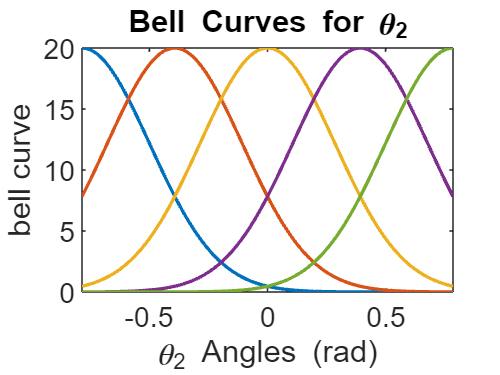

    title('Bell Curves for \theta_1')
    xlim([min(theta1),max(theta1)])
    
    figure 
    grid on
    plot(theta2test,bell_2new,'linewidth',1)
    xlabel('\theta_2 Angles (rad)')
    ylabel('bell curve')

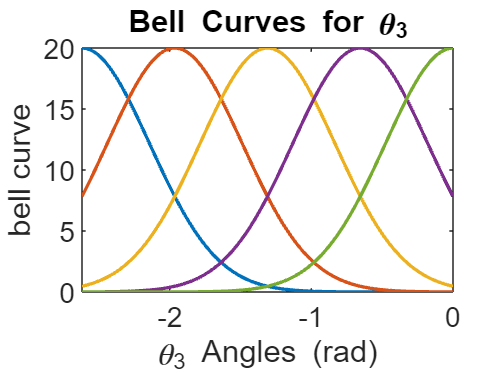

    title('Bell Curves for \theta_2')
    xlim([min(theta2),max(theta2)])
    
    figure 
    grid on
    plot(theta3test,bell_3new,'linewidth',1)
    xlabel('\theta_3 Angles (rad)')
    ylabel('bell curve')

    title('Bell Curves for \theta_3')
    xlim([min(theta3),max(theta3)])
    
    
    %We are going to smooth out the GmaxCube grid using a Gaussian "kernel". A
    %kernel is just an N-D grid of the same dimensions, where the value at each
    %position in the kernal tells us how much of the corresponding value in the
    %GmaxCube to add there. It's basically a weighted sum. If you were to make
    %c above = 300, then only 1 sensory cell would be active at a time, and the
    %resulting kernel would be a 3D cube of all 0s except for a 1 in the very
    %center. This means that the value that is already there makes up 100% of
    %the weight, because none of the other sensory cells are active, anyway. 
    %To make the kernel in a general case, we'll use bellfuncnew to find how
    %active each sensory cell is at a given angle, reshape each one like we do
    %when calculating sens1bellBlock, sens2bellBlock, etc., then .* them
    %together.
    amplitudes1 = repmat(reshape(bell1funcnew(mean(theta1)),[5,1,1]),[1,5,5]);
    amplitudes2 = repmat(reshape(bell2funcnew(mean(theta2)),[1,5,1]),[5,1,5]);
    amplitudes3 = repmat(reshape(bell3funcnew(mean(theta3)),[1,1,5]),[5,5,1]);
    kernel = amplitudes1.*amplitudes2.*amplitudes3;
    
    %The only adjustment we have to make to the kernel is to normalize it so
    %that its sum along all directions is 1. For best results, the kernel
    %should get to 0 before the limits of each theta. That is, in the "Bell
    %Curves for \theta_1" plot, the yellow bell curve should get close to 0 at
    %the edges. NSS.
    kernel = kernel/sum(kernel,"all");
    
    %Convolve GmaxCube with the kernel. Then save it in the shape we need for
    %subsequent calculations, as a column vector. NSS.
    Gmax_bell_new = convn(GmaxCube, kernel, 'same');
    Gmax_bell_new = Gmax_bell_new(:);
    
    %This approach with wide bell curves and the convolution is an alternative
    %to the erfs and nerfs, so I commented those out everywhere. It also means
    %we no longer need the "back propagation" step, so I commented that out,
    %too. If this approach works, I think it is quite neat, because we can
    %calculate all the network values ahead of time. NSS.

## Combos

    hSensoryScatter = figure;
    set(hSensoryScatter, 'Visible', 'on');
    v = VideoWriter('Sensory Field');
    v.FrameRate = numSteps/tmax;
    open(v);
    
    Usomanew = NaN(size(th1list));
    Ucomp_bell = NaN(5*5*5,numSteps);
    Ucomp_erf = NaN(5*5*5,numSteps);
    Ucomp_nerf = NaN(5*5*5,numSteps);
    Ucomp_all = NaN(5*5*5,numSteps);
    C = .1; %uF
    %Usoma = NaN(size(th1list));
    for i = 1:numSteps

Bell Curves

        sensor1bell = bell1funcnew(th1list(i));
        sensor2bell = bell2funcnew(th2list(i));
        sensor3bell = bell3funcnew(th3list(i));

Use Ucomp to insert whichever you want out.   

## Usoma

    %   %Calculate contribution of each sensor to each compartment     
        sens1block = repmat(reshape(sensor1bell,[5,1,1]),[1,5,5]);
        sens2block = repmat(reshape(sensor2bell,[1,5,1]),[5,1,5]);
        sens3block = repmat(reshape(sensor3bell,[1,1,5]),[5,5,1]);
    
    % bell
        bperm = max(0, sens1block + sens2block + sens3block - 2);
        bellCurveMax(i) = max(bperm,[],'all');
        Ucomp_bell(:,i) = R*bperm(:);
    %     Gsyn_bell(:,i) = min(max(Ucomp_bell(:,i)/R,0),1).*Gmax_bell_OG;
        Gsyn_bell(:,i) = min(max(Ucomp_bell(:,i)/R,0),1).*Gmax_bell_new;
        Gbell(i) = 1 + sum(Gsyn_bell(:,i));

#### New Usoma for Bell Curve:

        %A couple of these lines didn't use "Gsyn_bell" and "Gbell", so I
        %updated this to make sure it did. NSS.
        Usomanew_SSbell(i) = sum(Evec.*Gsyn_bell(:,i))./Gbell(i);
        if i == 1
            Usomanew_bell(i) = Usomanew_SSbell(i);
        else
            delbU(i) = dt/C*(-Usomanew_bell(i-1) + sum(Gsyn_bell(:,i).*(Evec - Usomanew_bell(i-1)),'all'));
            Usomanew_bell(i) = Usomanew_bell(i-1) + delbU(i);
        end

#### Calculate foot position:

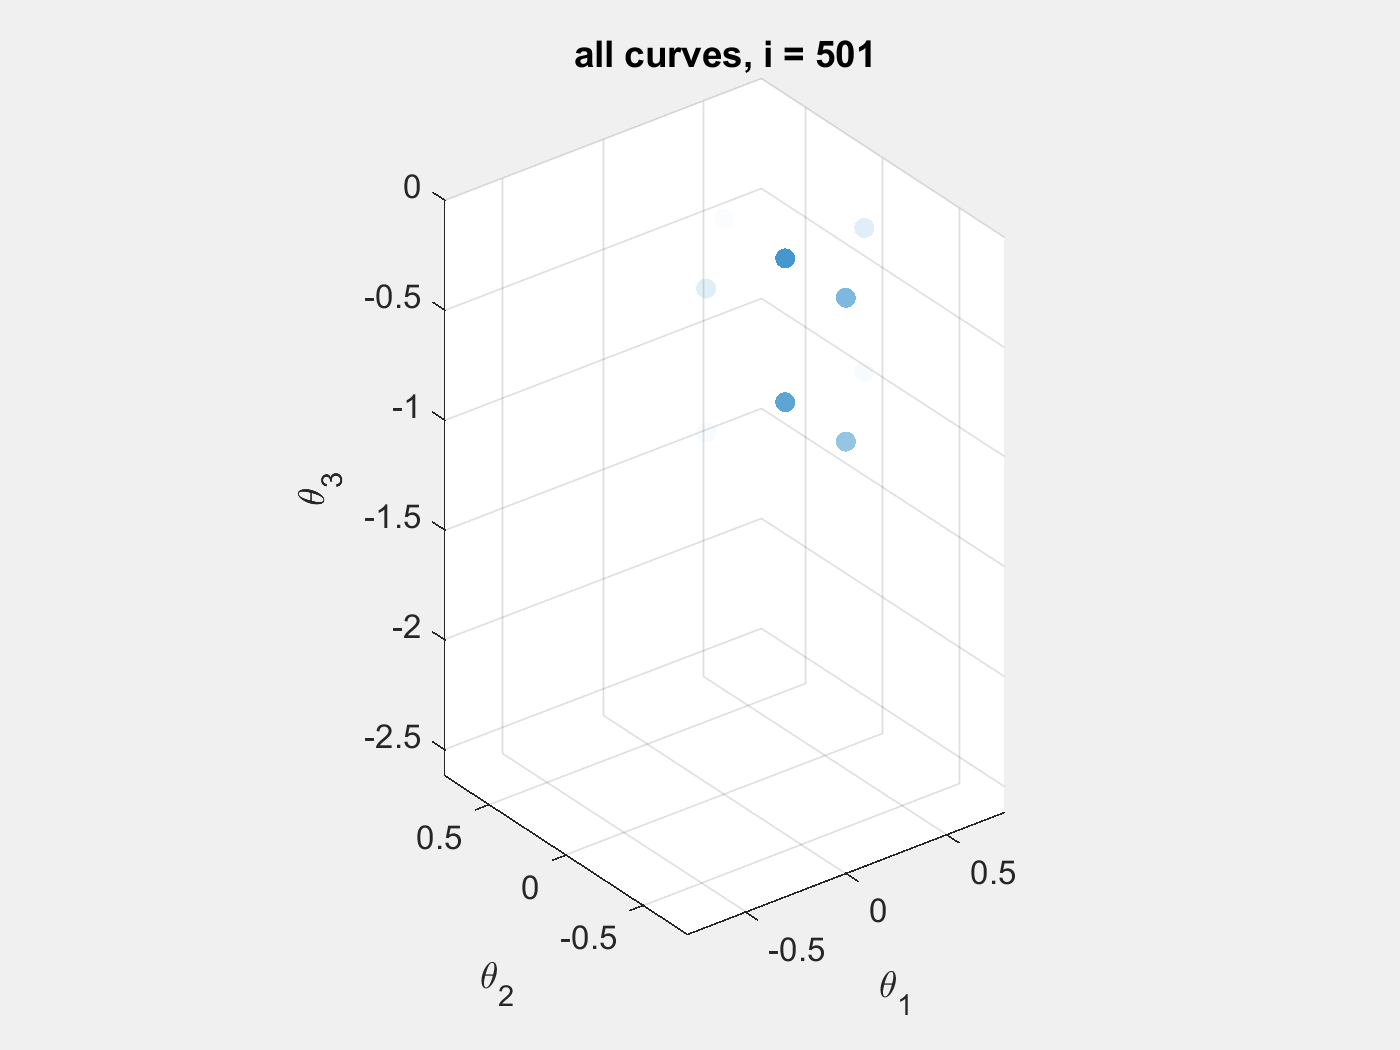

        %Calculate foot position
        exp_omega_skew1 = I + (omega_skew1).*sin(th1list(i)) + (omega_skew1)^2.*(1-cos(th1list(i)));
        exp_omega_skew2 = I + (omega_skew2).*sin(th2list(i)) + (omega_skew2)^2.*(1-cos(th2list(i)));
        exp_omega_skew3 = I + (omega_skew3).*sin(th3list(i)) + (omega_skew3)^2.*(1-cos(th3list(i)));
        % calculate translation
        t1 = (I-exp_omega_skew1)*(cross(omega1,v1)) + omega1*(omega1)'*(v1)*(th1list(i));
        t2 = (I-exp_omega_skew2)*(cross(omega2,v2)) + omega2*(omega2)'*(v2)*(th2list(i));
        t3 = (I-exp_omega_skew3)*(cross(omega3,v3)) + omega3*(omega3)'*(v3)*(th3list(i));
        % calculate the matrix exponential
        exp_Twist_skew1 = [exp_omega_skew1 t1;...
                           0 0 0 1];
        exp_Twist_skew2 = [exp_omega_skew2 t2;...
                           0 0 0 1];
        exp_Twist_skew3 = [exp_omega_skew3 t3;...
                           0 0 0 1];
        % compose the structure equation
        g_foot_thorax = exp_Twist_skew1*exp_Twist_skew2*exp_Twist_skew3*g_foot_thorax_zero;
    
        Py(i) = g_foot_thorax(2,4);
    
        %scatterplot stuff
        if i == 1
            sc3 = scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),'filled','MarkerFaceAlpha','flat','AlphaDataMapping','none','AlphaData',reshape(bperm,[],1));
            title(sprintf('all curves, i = %i',i))

            xlabel('\theta_1')
            ylabel('\theta_2')
            zlabel('\theta_3')
            axis equal
        else
            sc3.AlphaData = reshape(bperm,[],1);
            title(sprintf('all curves, i = %i',i))
        end
        drawnow
        frame = getframe(hSensoryScatter);
        writeVideo(v,frame);
        %end scatterplot stuff
    end
    close(v);
    
    figure
    plot(t,bellCurveMax)
    hold on
    title('max of bell curve matrix')
    ax = gca;
    ax.XLim(1) = 0;
    ax.YLim(1) = 0;
    
    scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),[],reshape(output(:,:,:,5),[],1),'filled')
    title('P_y')
    xlabel('\theta_1')
    ylabel('\theta_2')
    zlabel('\theta_3')
    colorbar 
    
    figure
    sc3 = scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),'filled','MarkerFaceAlpha','flat','AlphaDataMapping','none','AlphaData',reshape(bperm,[],1))
    title('bperm')
    xlabel('\theta_1')
    ylabel('\theta_2')
    zlabel('\theta_3')
    axis equal

### Plot the result:

    [X,Y] = meshgrid(1:125,1:501);
    X = X';
    Y = Y';
    figure
    surf(X,Y,Ucomp_bell,'edgealpha',0)
    xlabel('compartment')
    ylabel('time')
    zlabel('activity')
    title('visualization of compartment activity')
    colorbar
    ylim([0,numSteps])
    xlim([1,125])
    view(0,90)

#### Bell Curve Results:

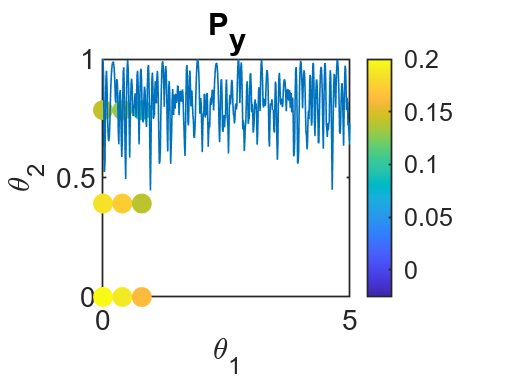

sc3 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [-0.7854 -0.3927 0 0.3927 0.7854 -0.7854 -0.3927 0 0.3927 0.7854 -0.7854 -0.3927 0 0.3927 0.7854 -0.7854 -0.3927 0 0.3927 0.7854 -0.7854 -0.3927 0 0.3927 0.7854 -0.7854 -0.3927 0 0.3927 0.7854 -0.7854 -0.3927 0 0.3927 0.7854 … ]
              YData: [-0.7854 -0.7854 -0.7854 -0.7854 -0.7854 -0.3927 -0.3927 -0.3927 -0.3927 -0.3927 0 0 0 0 0 0.3927 0.3927 0.3927 0.3927 0.3927 0.7854 0.7854 0.7854 0.7854 0.7854 -0.7854 -0.7854 -0.7854 -0.7854 -0.7854 -0.3927 -0.3927 -0.3927 … ]
              ZData: [-2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -2.6180 -1.9635 -1.9635 -1.9635 … ]
           

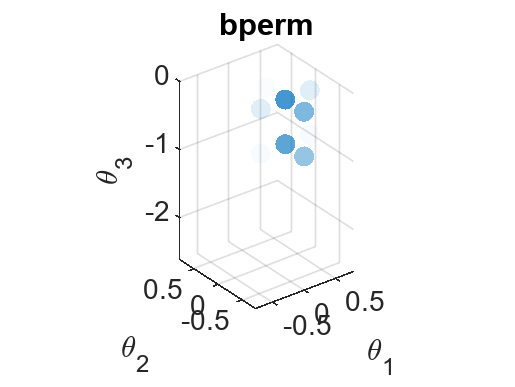

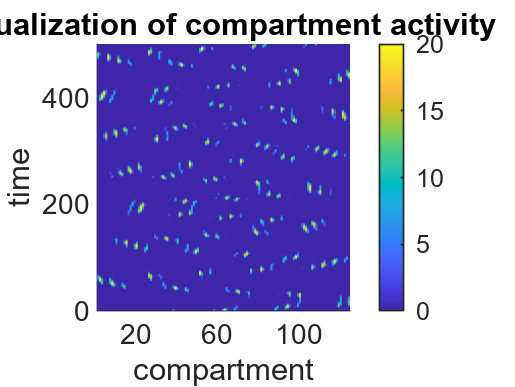

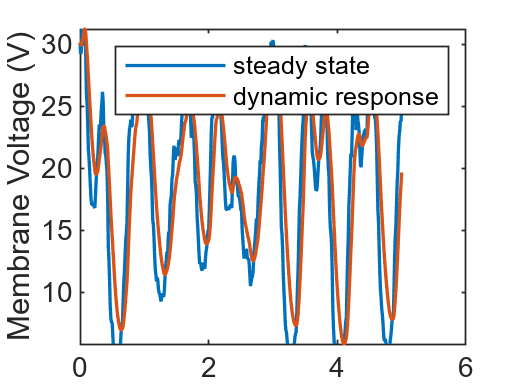

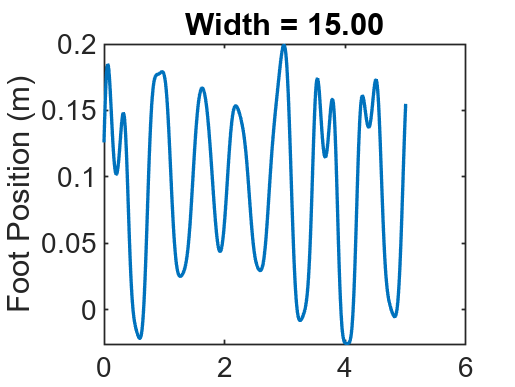

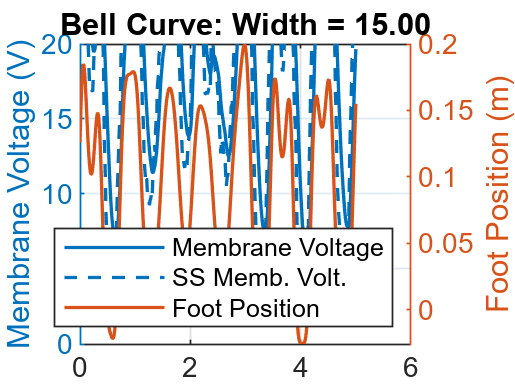

    figure 
    plot(t,Usomanew_SSbell,'linewidth',1)
    hold on
    plot(t,Usomanew_bell,'linewidth',1)
    ylabel('Membrane Voltage (V)')
    ylim([min(Usomanew_bell),max(Usomanew_bell)])
    legend('steady state','dynamic response')
    
    figure
    plot(t,Py,'linewidth',1)
    ylabel('Foot Position (m)')
    ylim([minPy,maxPy])
    title(sprintf('Width = %0.2f',c));
    drawnow
    
    figure 
    grid on
    yyaxis left
    plot(t,Usomanew_bell,'linewidth',1)
    hold on
    plot(t,Usomanew_SSbell','linewidth',1)
    ylabel('Membrane Voltage (V)')
    ylim([0,R])
    hold on
    yyaxis right

    plot(t,Py,'linewidth',1)
    ylabel('Foot Position (m)')
    ylim([minPy,maxPy])
    legend('Membrane Voltage','SS Memb. Volt.','Foot Position','location','south')
    title(sprintf('Bell Curve: Width = %0.2f',c));
    drawnow
end